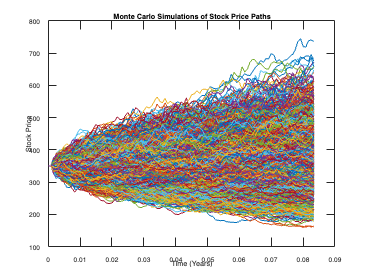

% Parameters
S0 = 350;             % Current stock price
K = S0 + 20;          % Strike price
r = 0.05;             % Risk-free interest rate
sigma = 0.6802;       % Volatility from previous section
T = 1/12;             % Time to maturity in years (1 month)
num_simulations = 10000; % Number of Monte Carlo simulations
num_steps = 100;      % Number of time steps in each simulation

% Time increment
dt = T / num_steps;

% Initialize array to store end stock prices
end_prices = zeros(num_simulations, 1);
option_prices = zeros(num_simulations, 1);

% Monte Carlo simulation
for i = 1:num_simulations
    % Generate a path of stock prices
    path = zeros(num_steps, 1);
    path(1) = S0;
    
    for t = 2:num_steps
        % Wiener process
        Z = randn; % Standard normal random variable
        path(t) = path(t-1) * exp((r - 0.5 * sigma^2) * dt + sigma * sqrt(dt) * Z);
    end
    
    end_prices(i) = path(end); % Store end stock price
    option_prices(i) = exp(-r * T) * max(path(end) - K, 0); % Discounted payoff
    
    % Plot the path for visualization
    plot(0:dt:T, [S0; path]);
    hold on;
end
hold off;
title('Monte Carlo Simulations of Stock Price Paths');
xlabel('Time (Years)');
ylabel('Stock Price');


% Calculate call option payoff for each simulation
payoffs = max(end_prices - K, 0);

% Discounted average payoff as call option price
call_price = exp(-r * T) * mean(payoffs);

% Calculate statistics
std_dev_price = std(payoffs);

% Display results
fprintf('Estimated Call Option Price: %.4f\n', call_price);

Estimated Call Option Price: 19.4608


fprintf('Standard Deviation of Payoffs: %.4f\n', std_dev_price);

Standard Deviation of Payoffs: 38.8747


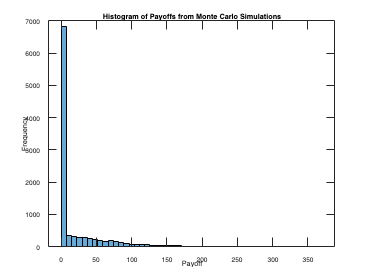


% Optional histogram of the payoffs
figure;
histogram(payoffs, 50);
title('Histogram of Payoffs from Monte Carlo Simulations');
xlabel('Payoff');
ylabel('Frequency');

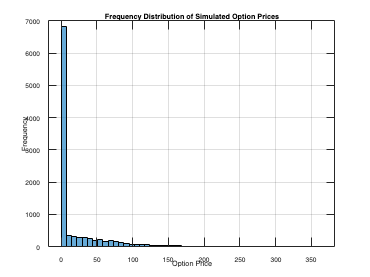


% Plot histogram of the option prices 
figure;
histogram(option_prices, 50);
title('Frequency Distribution of Simulated Option Prices');
xlabel('Option Price');
ylabel('Frequency');
grid on;